clear;clf;
%load common data
load("ChanName.mat");
load('Pair54.mat');
load('timeRawTrace.mat')

%load personal data
for i = 1:4
    rawTracePerson = sprintf("Person%d\\Person%d\\rawTracePerson%d.mat",i,i,i);
    OSPerson = sprintf("Person%d\\Person%d\\OSPerson%d.mat",i,i,i);

    rawTracePerson_info = whos('-file', rawTracePerson);
    rawTracePerson_name = {rawTracePerson_info.name};
    OSPerson_info = whos('-file',OSPerson);
    OSPerson_name = {OSPerson_info.name};
    
    load(rawTracePerson);
    load(OSPerson);
    for j=1:length(rawTracePerson_name)
        eval(sprintf("%s_P%d = %s;",rawTracePerson_name{j},i,rawTracePerson_name{j}));
    end
  
    for j=1:length(OSPerson_name)
        eval(sprintf("%s_P%d = %s;",OSPerson_name{j},i,OSPerson_name{j}));
    end
    
end

%rawTrace
fs = 300;
t = 0:1/fs:7-(1/fs);
numChannels = 19;
channelNames = [];
channelid = [1:8,10:16,19:20,23:24];

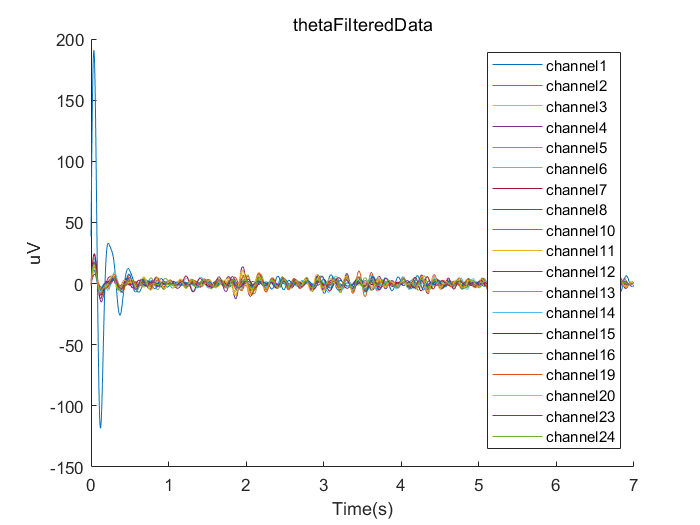

for i = 1:length(channelid)
    channelNames = [channelNames, sprintf("channel%d",channelid(i))];
end
colors = lines(numChannels);
thetaFreqRange = [4 8]; % Theta频带的频率范围（以赫兹为单位）
%bandpass filter
% 计算滤波器参数
filterOrder = 3; % 滤波器阶数
thetaWn = thetaFreqRange / (fs/2); % 归一化的频率范围
% 设计并应用带通滤波器
[b1, a1] = butter(filterOrder, thetaWn, 'bandpass'); % 设计Butterworth带通滤波器
figure;
hold on;
thetaFiltereddata = [];
for i = 1:numChannels
    thetaFilteredData = filtfilt(b1, a1, dataTrial_P1(:,2,i)); % 应用滤波器(零相位滤波）
    plot(t,thetaFilteredData, 'color', colors(i, :));
    thetaFiltereddata = horzcat(thetaFiltereddata,thetaFilteredData);
end
hold off;
legend(channelNames);
title('thetaFilteredData');
xlabel('Time(s)');
ylabel('uV');

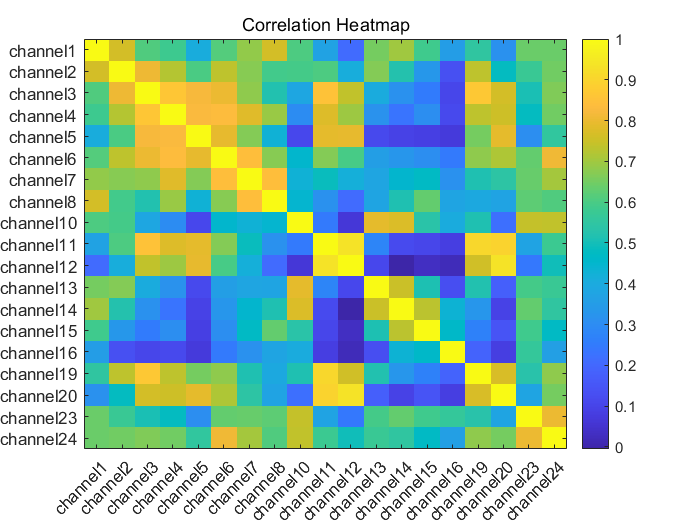

correlationMatrix = corrcoef(thetaFiltereddata);
figure;
imagesc(correlationMatrix);
colorbar; % 添加颜色刻度条
title('Correlation Heatmap'); % 添加标题
xticks(1:numChannels);
yticks(1:numChannels);
xticklabels(channelNames);
yticklabels(channelNames);
xtickangle(45);